clear all; close all; clc;
warning('off','all');

clear all;
%% Global variables
global x_result

%% Initialization of the optimization routine
x_result = [];
x_guess  = [0.05; 0.125];  

%% Optimization routine
options = optimset('PlotFcns',@optimplotfval);
disp('Optimization started...')

Optimization started...


disp(' ')

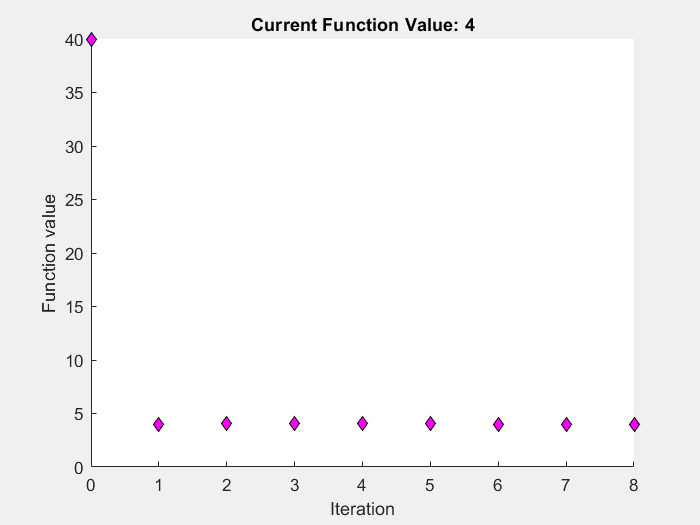


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x_opt =     0.5000
    0.1250


V_result = 4.0000

[x_opt, V_result] = fmincon('Opti_Shears', x_guess,[],[],[],[],[0,0],[0.5,0.25],[], options)

disp(' ')

disp('...optimization finished!')

...optimization finished!


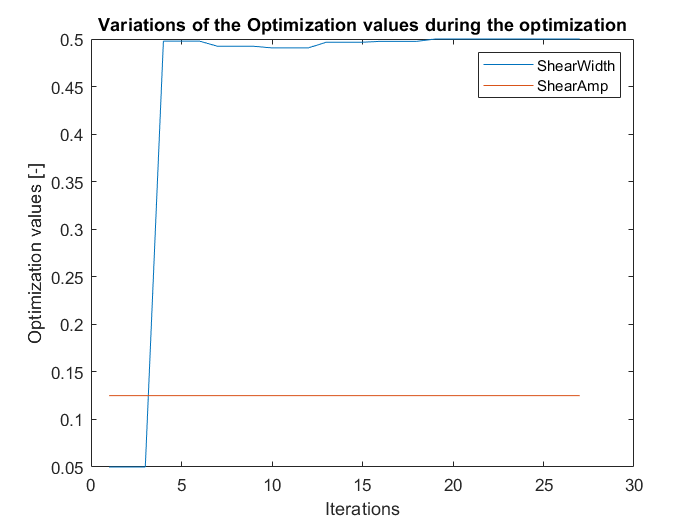


%% Plots
figure;
plot(x_result); legend('ShearWidth ','ShearAmp');
xlabel('Iterations')
ylabel('Optimization values [-]')
title('Variations of the Optimization values during the optimization')